# 29 Jan; SWC - Debugging Image Cropping Code

#### **Associated script: *****dropCropMULTI.m***

**Problem:** A bug was found in initial code written for cropping images (dated: 28-Jan) when bulk tested with 'SO5_13umL-7Wat_umL-10kfps x4mag_sh50_...' series dataset (located in SWC hard drive data). 

It was noticed only 1-3 drops on average were cropped from an individual frame, indicating that some drops have been 'lost' during the pre-processing stage. 

In some cases, no drops were extracted and cropped from a frame, resulting in code terminating. 

**Summary: **This note explains the troubleshooting process, performed using 2 video files: 

1) SO5cSt 16uL_15 uL TRITON_0.5 mM 034.avi

2) SO5_13umL-7Wat_umL-10kfps x4mag_sh50_C001H001S0026

**Outcome**: The noise object removal process is now performed after morphological fill (instead of after tresholding). 

## 1) Problem Identification: Noise Object Removal Step 

- Load video 

vid_file_name = 'SO5_13umL-7Wat_umL-10kfps x4mag_sh50_C001H001S0026.avi';
vid = VideoReader(vid_file_name); %read video 
totframes = vid.NumFrames %check total num of frames in video

totframes = 966

- Background image generation

n = 200;    % number of frames to use for background generation  
idx = round(linspace(1,totframes,n)); %vector of index of frame number to be extracted

frameMat = []; 

% for loop to create matrix of frames - for generating background image
for i=1:numel(idx)
    frame = read(vid,idx(i)); 
    frameMat = cat(3,frameMat,frame);
end

tic
med_pix = median(frameMat,3); %compute median of each pixel across all frames in matrix
toc

Elapsed time is 0.237300 seconds.



tic
max_pix = mode(frameMat,3); %compute mode of each pixel across all frames in matrix
toc

Elapsed time is 2.613330 seconds.


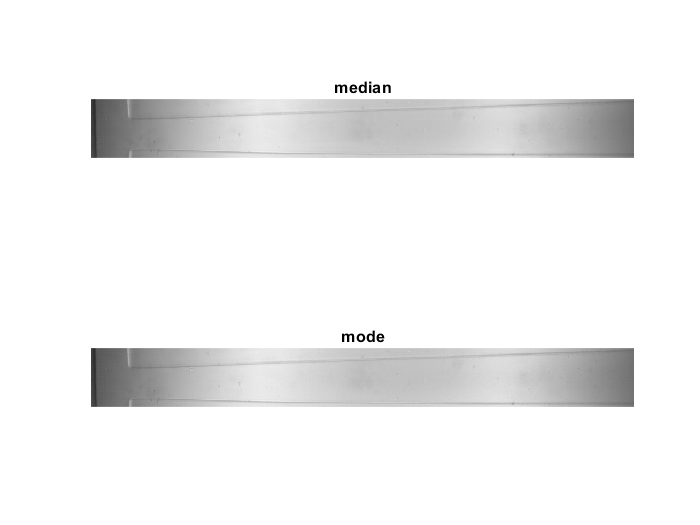


%show generated background 
figure; 
subplot(2,1,1); imshow(med_pix); title('median')
subplot(2,1,2); imshow(max_pix); title('mode')

**Additional note**: background generated based on 'mode' pixel isn't as high quality as that using 'median', but will see later that it doesn't actually makes much difference.  

- Load sample video frame

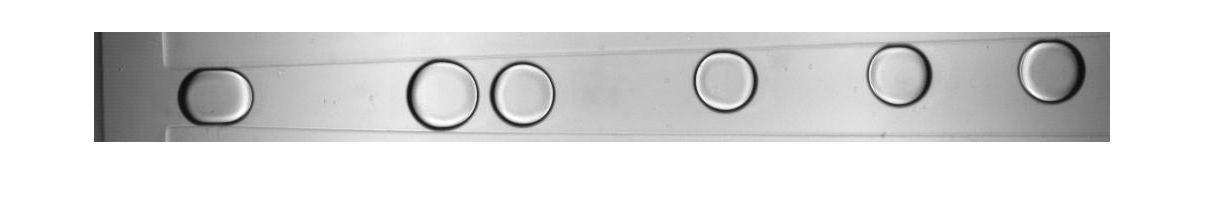

% Load image
I = imread('3456.jpg');  

% check images loaded correctly
figure; imshow(I); 

- Background subtraction 

***Note****: Original image will be subtracted with two different background: 1) based on 'median', and 2) based on 'mode'. This demonstrates how the method for background generation has marginal effect on the pre-processing output. *

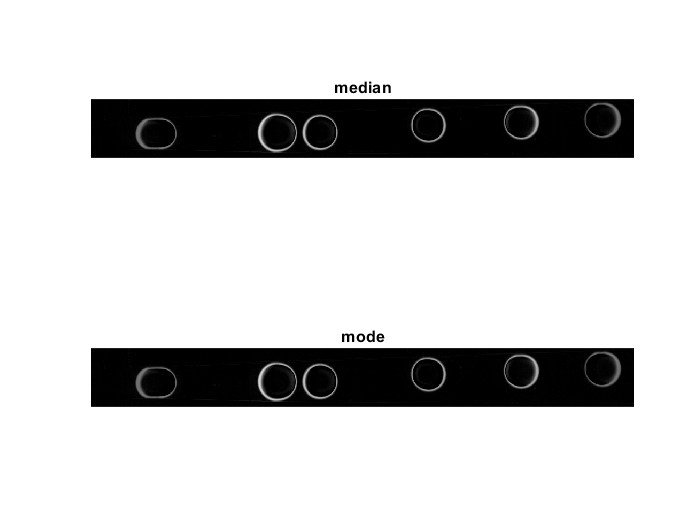

%Median background generation
subMed = med_pix - I; 

%Mode background generation
subMax = max_pix - I; 

figure; 
subplot(2,1,1); imshow(subMed); title('median')
subplot(2,1,2); imshow(subMax); title('mode')

- Image Binarisation

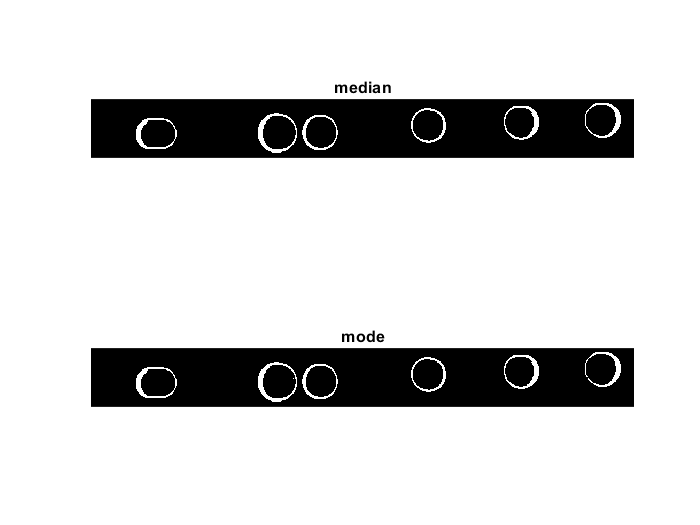

treshold = 0.2;
bin1= imbinarize(subMed, treshold); %imshow(bin1)
bin2= imbinarize(subMax, treshold); %imshow(bin2)

figure; 
subplot(2,1,1); imshow(bin1); title('median')
subplot(2,1,2); imshow(bin2); title('mode')

**So far, the processing steps give results that would be as expected. **

**Now, will look at the sequence in which noise object removal stage is carried out. This step works on the basis that any connected area less than a user-defined pixel area (in this case, <1000) will be removed.  **

### Case 1: Noise object removal performed directly after tresholding (binarisation) 

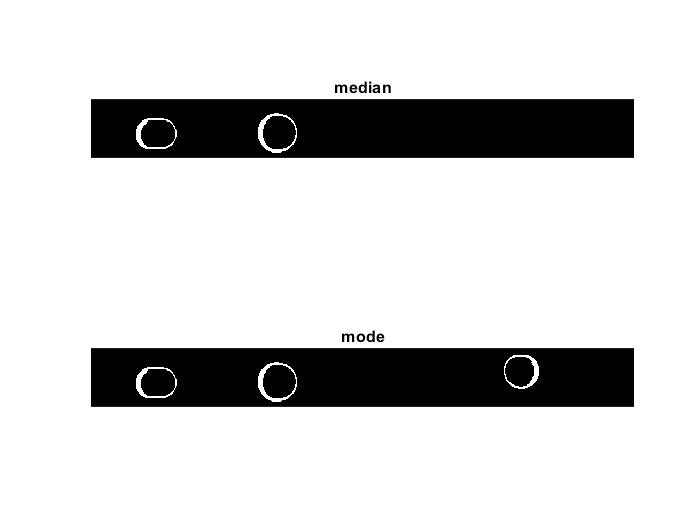

cbin1 = bwareaopen(bin1,1000);
cbin2 = bwareaopen(bin2,1000);
figure; 
subplot(2,1,1); imshow(cbin1); title('median')
subplot(2,1,2); imshow(cbin2); title('mode')

**                                                OUTPUT: DROPS HAVE BEEN LOST!**

### Case 2: Noise object removal performed after morphological fill stage

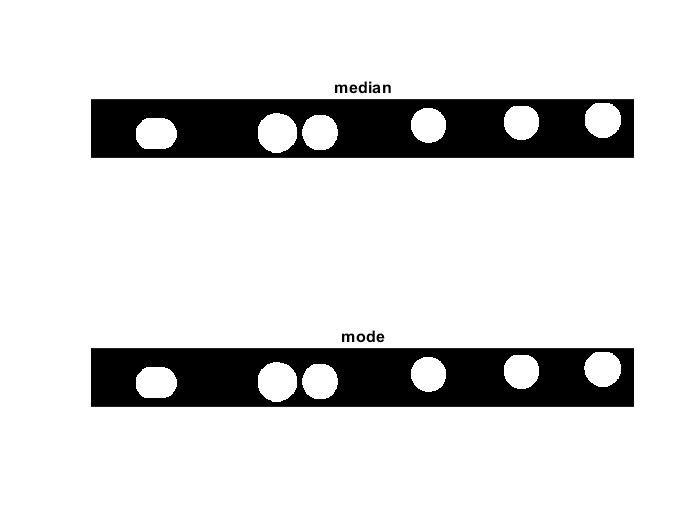

fill1 = bwconvhull(bin1, 'objects'); 
fill2 = bwconvhull(bin2, 'objects'); 
figure; 
subplot(2,1,1); imshow(fill1); title('median')
subplot(2,1,2); imshow(fill2); title('mode')


cfill1 = bwareaopen(fill1,1000);
cfill2 = bwareaopen(fill2,1000);
figure; 
subplot(2,1,1); imshow(cfill1); title('median')
subplot(2,1,2); imshow(cfill2); title('mode')

**                                                        OUTPUT: NO DROPS LOST!**

## **2) Validation: Another Example **

The previous example does not actually have noise objects in the frame. 

So, here's one with noise objects... 

- Load video 

vid_file_name2 = 'SO5cSt 16uL_15 uL TRITON_0.5 mM 034.avi';
vid2 = VideoReader(vid_file_name2); %read video 
totframes2 = vid2.NumFrames %check total num of frames in video

totframes2 = 256

- Background image generation

n = 200;    % number of frames to use for background generation  
idx = round(linspace(1,totframes2,n)); %vector of index of frame number to be extracted

frameMat2 = []; 

% for loop to create matrix of frames - for generating background image
for i=1:numel(idx)
    frame2 = read(vid2,idx(i)); 
    frameMat2 = cat(3,frameMat2,frame2);
end

tic
med_pix2 = median(frameMat2,3); %compute median of each pixel across all frames in matrix
toc

Elapsed time is 2.925663 seconds.


tic
max_pix2 = mode(frameMat2,3); %compute median of each pixel across all frames in matrix
toc

Elapsed time is 45.914544 seconds.


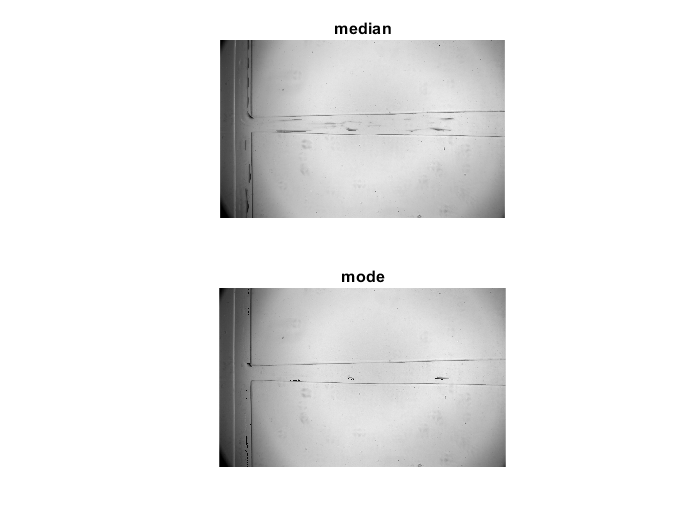


%show generated background 
%method this time
figure; 
subplot(2,1,1); imshow(med_pix2); title('median')
subplot(2,1,2); imshow(max_pix2); title('mode')

- Load sample video frame

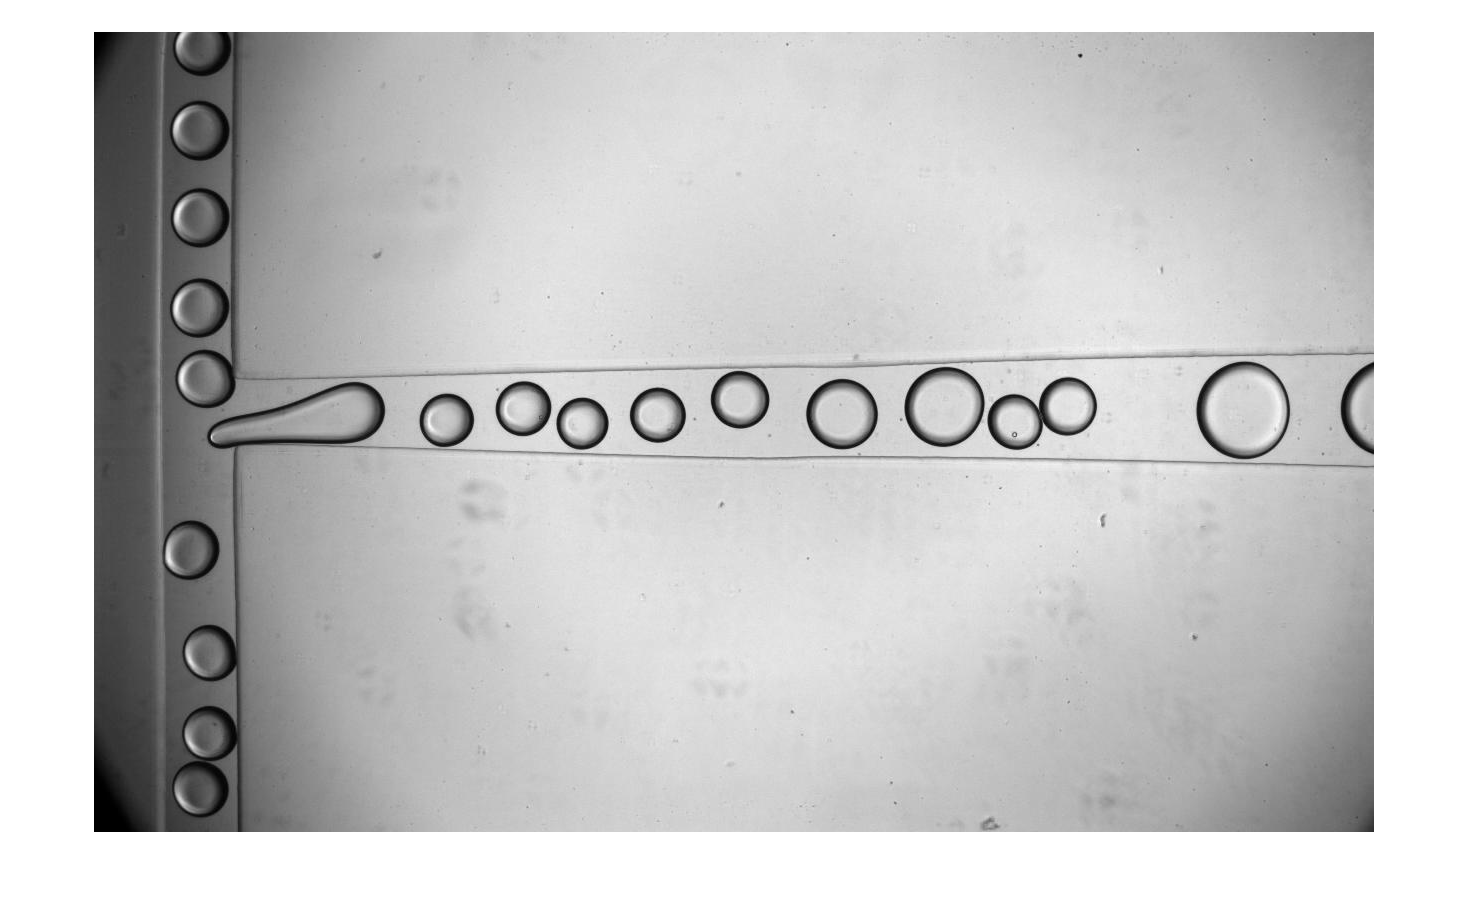

% Load image
I2 = imread('1.jpg');  

% check images loaded correctly
figure; imshow(I2); 

- Background subtraction 

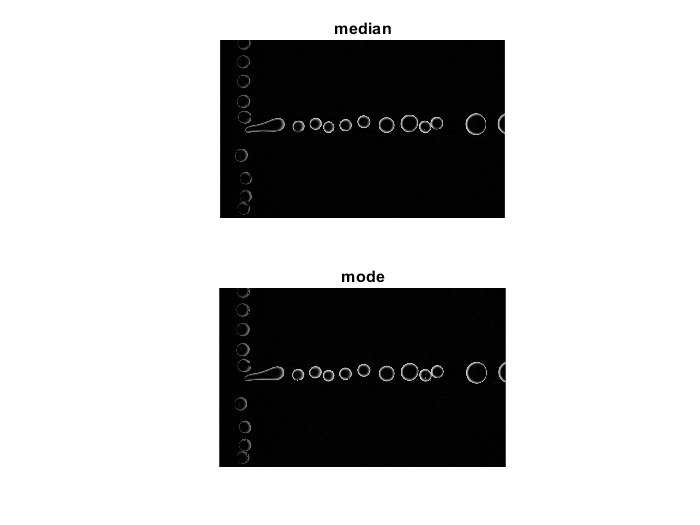

%Median background generation
subMed2 = med_pix2 - I2; 
subMax2 = max_pix2 - I2;

figure; 
subplot(2,1,1); imshow(subMed2); title('median')
subplot(2,1,2); imshow(subMax2); title('mode')

- Image Binarisation

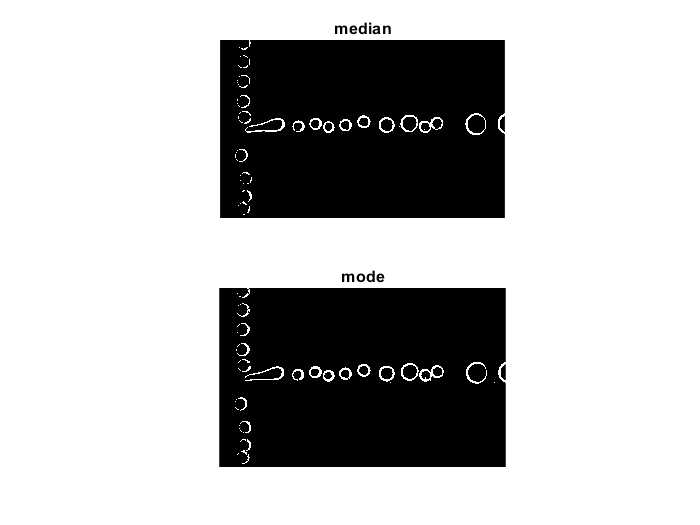

treshold = 0.2;
bin1_2= imbinarize(subMed2, treshold); 
bin2_2= imbinarize(subMax2, treshold);
figure; 
subplot(2,1,1); imshow(bin1_2); title('median')
subplot(2,1,2); imshow(bin2_2); title('mode')

- Morphological fill

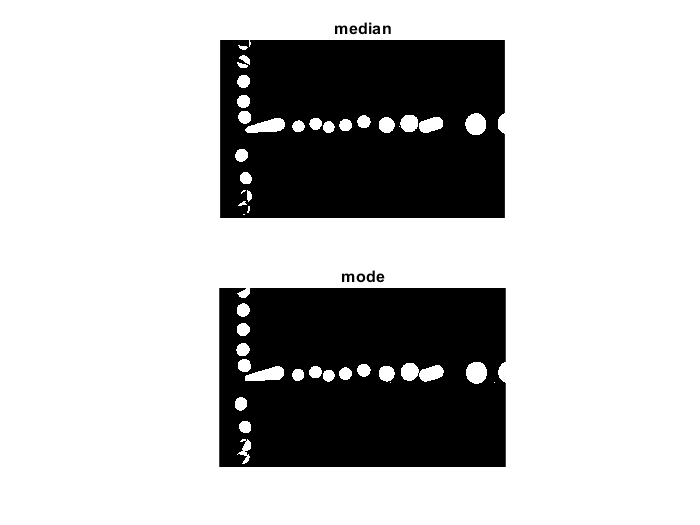

fill1_2 = bwconvhull(bin1_2, 'objects'); 
fill2_2 = bwconvhull(bin2_2, 'objects'); 

figure; 
subplot(2,1,1); imshow(fill1_2); title('median')
subplot(2,1,2); imshow(fill2_2); title('mode')

can see there are speckles in the images. Check areas are each ROIs:

ROI1 = regionprops('table',fill1_2) 

ROI1 = 41×3 table
    Area        Centroid                  BoundingBox          
    ____    ________________    _______________________________

    2700    97.488    518.92    69.5    489.5       57       59
    2783    106.29    276.51    76.5    246.5       59       60
       7        78        95    77.5     91.5        1        7
     841    100.97    116.01    77.5    100.5       49       28
    2702    107.05    186.21    77.5    156.5       59       59
       1        80        88    79.5     87.5        1        1
       1        81        20    80.5     19.5        1        1
       1        81        86    80.5     85.5        1        1
       1        81       748    80.5    747.5        1        1
     592    104.25    34.336    81.5     23.5       44       21
       2      82.5      83.5    81.5     82.5        2        2
     413    101.61    737.91    81.5    729.5  


ROI2 = regionprops('table', fill2_2) 

ROI2 = 32×3 table
    Area        Centroid                  BoundingBox           
    ____    ________________    ________________________________

    2703    97.461     518.9     69.5    489.5       57       59
    2796    106.35    276.55     76.5    246.5       59       60
    2753    106.74    99.286     77.5     69.5       58       59
    2745    107.06    186.32     77.5    156.5       59       59
       5        81        19     80.5     16.5        1        5
       1        81       748     80.5    747.5        1        1
    1612    113.05    24.044     81.5      0.5       56       44
       4      82.5       745     81.5    743.5        2        3
    2805    112.46    347.67     82.5    318.5       60       58
    3003    119.15    725.05     83.5    674.5       60      111
    2421     116.6    621.68     89.5    593.5       54       56
       9        90       701     8

By inspection, the areas of 'proper' drops are >2000 pixels.

It is also interesting to note that with median background generation method, more noise objects were produced.

- Noise object removal

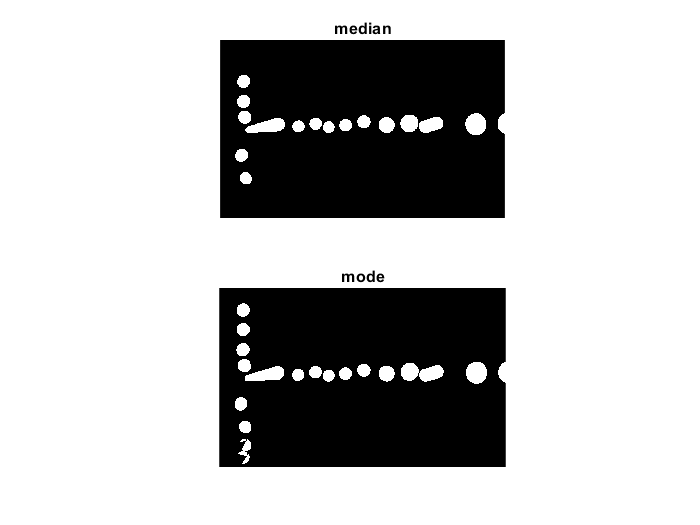

cfill1_2 = bwareaopen(fill1_2,2000);
cfill2_2 = bwareaopen(fill2_2,2000);

figure; 
subplot(2,1,1); imshow(cfill1_2); title('median')
subplot(2,1,2); imshow(cfill2_2); title('mode')

cROI1 = regionprops('table',cfill1_2) 

cROI1 = 16×3 table
    Area        Centroid                    BoundingBox             
    ____    ________________    ____________________________________

    2700    97.488    518.92      69.5     489.5        57        59
    2783    106.29    276.51      76.5     246.5        59        60
    2702    107.05    186.21      77.5     156.5        59        59
    2774    112.19    347.74      82.5     318.5        59        58
    2403    116.48     621.8      89.5     593.5        54        56
    7994    212.59    388.78     113.5     350.5       178        67
    2348    353.17    388.66     325.5     361.5        55        54
    2478    430.11    377.03     401.5     349.5        57        55
    2209    488.97    392.18     462.5     365.5        53        53
    2500    564.51    383.64     536.5     355.5        56        56
    2730    646.71    368.18     617.5     339.5  


cROI2 = regionprops('table', cfill2_2) 

cROI2 = 18×3 table
    Area        Centroid                  BoundingBox           
    ____    ________________    ________________________________

    2703    97.461     518.9     69.5    489.5       57       59
    2796    106.35    276.55     76.5    246.5       59       60
    2753    106.74    99.286     77.5     69.5       58       59
    2745    107.06    186.32     77.5    156.5       59       59
    2805    112.46    347.67     82.5    318.5       60       58
    3003    119.15    725.05     83.5    674.5       60      111
    2421     116.6    621.68     89.5    593.5       54       56
    7960    212.69    388.65    113.5    350.5      178       67
    2370    353.17    388.77    325.5    361.5       55       54
    2489    430.08    377.12    401.5    349.5       57       55
    2225       489    392.08    462.5    365.5       53       53
    2505    564.51    383.66    5

**                                          OUTPUT: TINY SPECKLES REMOVED BUT NO DROPS LOST!**

Will show the remaining of the pre-processing steps...

- Remove objects outside of main channel 

delCriteria = 140; %if centroid position < delCritera

cROI1(cROI1.Centroid(:,1) < delCriteria, :) = []

cROI1 = 11×3 table
    Area        Centroid                    BoundingBox             
    ____    ________________    ____________________________________

    7994    212.59    388.78     113.5     350.5       178        67
    2348    353.17    388.66     325.5     361.5        55        54
    2478    430.11    377.03     401.5     349.5        57        55
    2209    488.97    392.18     462.5     365.5        53        53
    2500    564.51    383.64     536.5     355.5        56        56
    2730    646.71    368.18     617.5     339.5        59        58
    4073    748.72    382.77     712.5     347.5        72        71
    5141    851.09     375.1     810.5     335.5        81        80
    5815    948.99    382.15     893.5     345.5       110        73
    7362      1150    378.89    1102.5     329.5        94        98
    2305    1266.6    377.02    1247.5     330.5  

cROI2(cROI2.Centroid(:,1) < delCriteria, :) = []

cROI2 = 11×3 table
    Area        Centroid                    BoundingBox             
    ____    ________________    ____________________________________

    7960    212.69    388.65     113.5     350.5       178        67
    2370    353.17    388.77     325.5     361.5        55        54
    2489    430.08    377.12     401.5     349.5        57        55
    2225       489    392.08     462.5     365.5        53        53
    2505    564.51    383.66     536.5     355.5        56        56
    2740    646.68    368.21     616.5     339.5        60        58
    4074    748.72    382.77     712.5     347.5        72        71
    5150    851.12    375.17     810.5     335.5        81        80
    5830    949.04     382.2     893.5     345.5       110        73
    7373      1150    378.94    1102.5     329.5        94        99
    2306    1266.6    377.01    1247.5     330.5  

- plot final results

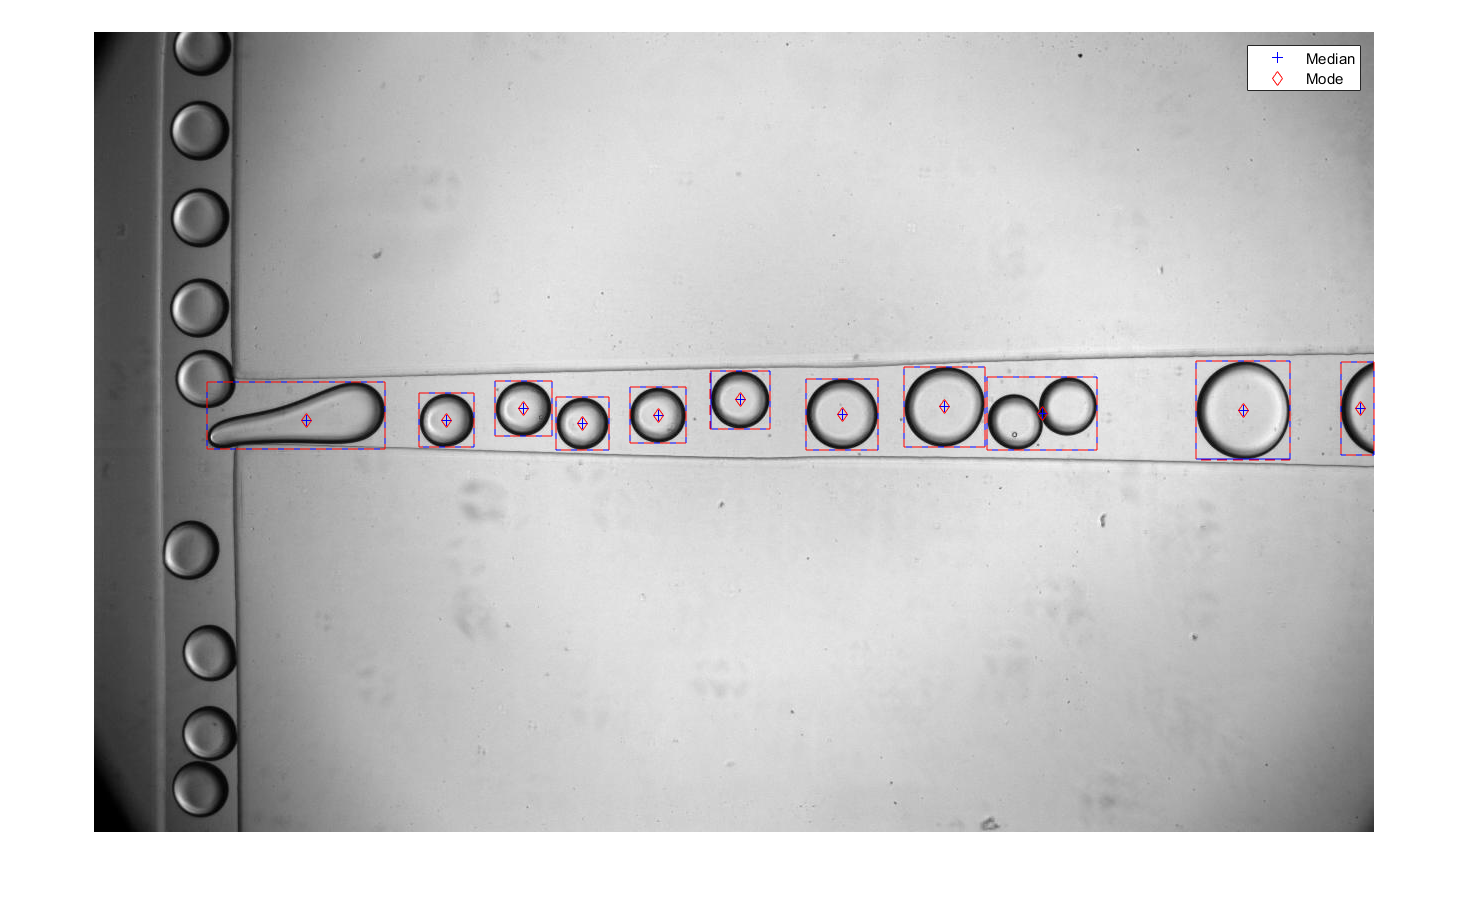

figure; imshow(I2);
hold on

% from cROI1 data
plot(cROI1.Centroid(:,1), cROI1.Centroid(:,2), 'b+')

for i=1:height(cROI1)
    rectangle('Position',cROI1.BoundingBox(i,:),'EdgeColor','b')
end
% from cROI2 data
plot(cROI2.Centroid(:,1), cROI2.Centroid(:,2), 'rd')

for i=1:height(cROI2)
    rectangle('Position',cROI2.BoundingBox(i,:),'EdgeColor','r','LineStyle', '--')
end

legend('Median','Mode')